%first order response
s1 = load("lab4_order1_3.mat")

s1 = struct with fields:
    data: [1×1 struct]
       t: [330×1 double]


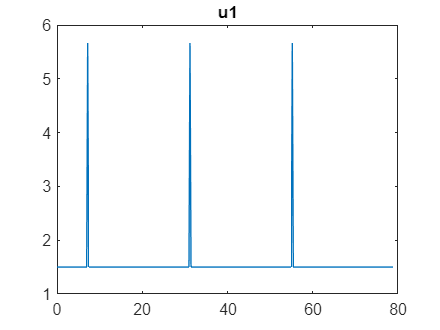


u = cell2struct(s1.data.InputData,"input_fields",1);
y = cell2struct(s1.data.OutputData,"output_fields",1);

plot(s1.t,u.input_fields); title(s1.data.InputName);

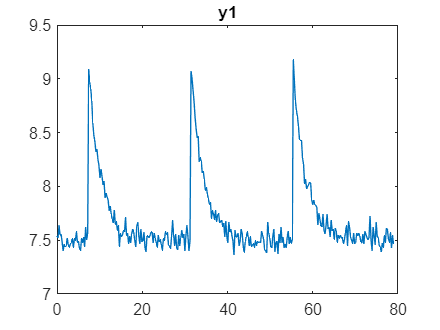

plot(s1.t,y.output_fields); title(s1.data.OutputName);


uid = u.input_fields(1:110);
yid = y.output_fields(1:110);
tid = s1.t(1:110);

uval = u.input_fields(111:330);
yval = y.output_fields(111:330);
tval = s1.t(111:330);

y_ss = 1/11*sum(yid(100:110,:))

y_ss = 7.5072

u_ss = 1/11*sum(uid(100:110,:))

u_ss = 1.5000

y0 = 0;
u0 = 0;

k = (y_ss-y0)/(u_ss-u0)

k = 5.0048

hs = tf(k,[63*y_ss/100 1])

hs =
 
    5.005
  ----------
  4.73 s + 1
 
Continuous-time transfer function.




ymax = max(yid);
y0 = 7.53;
t = 0.368*(ymax-y0)+y0;

A = -1/t;
B = k/t;
C = 1;
D = 0;

Hss1 = ss(A,B,C,D)

Hss1 =
 
  A = 
            x1
   x1  -0.1234
 
  B = 
           u1
   x1  0.6177
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




y_id_cap = lsim(hs,uid,tid);
y_val_cap = lsim(hs,uval,tval);


mse_id = mean(1/110*(yid)*sum((y_id_cap-yid).^2))

mse_id = 41.1407

mse_val = mean(1/220*(yval)*sum((y_val_cap-yval).^2))

mse_val = 20.8915

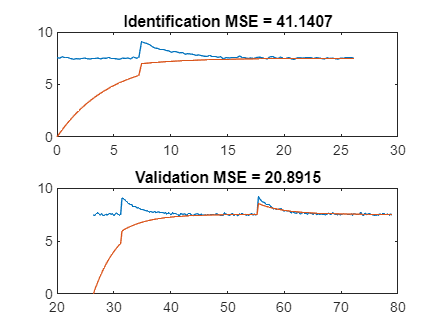


figure,
subplot(2,1,1);
plot(tid,yid,tid,y_id_cap); title("Identification MSE = " + string(mse_id))
subplot(2,1,2);
plot(tval,yval,tval,y_val_cap); title("Validation MSE = " + string(mse_val))


%second order impulse
s2 = load("lab4_order2_3.mat");

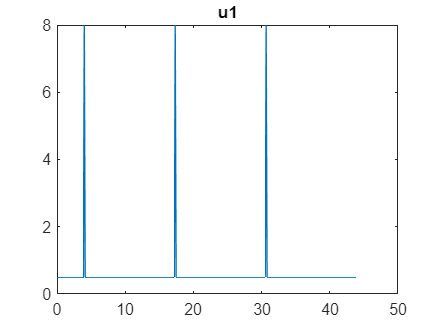


u = cell2struct(s2.data.InputData,"input_fields",1);
y = cell2struct(s2.data.OutputData,"output_fields",1);

figure,
plot(s2.t,u.input_fields); title(s2.data.InputName);

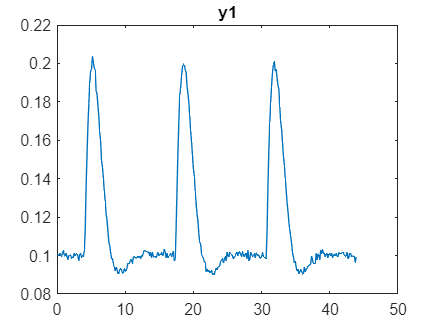

plot(s2.t,y.output_fields); title(s2.data.OutputName);


id = struct("u",u.input_fields(1:110),"y",y.output_fields(1:110),"t",s2.t(1:110));
val = struct("u",u.input_fields(111:330),"y",y.output_fields(111:330),"t",s2.t(111:330));

y_ss = 1/11*sum(id.y(100:110,:));
u_ss = 1/11*sum(id.u(100:110,:));
t1 = 5.2

t1 = 5.2000

t2 = 8.9

t2 = 8.9000

T0 = 2*(t2-t1)

T0 = 7.4000


ymax = max(yid);
y0 = 1/10*sum(yid(1:10,:))

y0 = 7.5025

t = 0.368*(ymax-y0)+y0;

A = -1/t;
B = k/t;
C = 1;
D = 0;

Hss1 = ss(A,B,C,D)

Hss1 =
 
  A = 
            x1
   x1  -0.1237
 
  B = 
          u1
   x1  0.619
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% la overshoot imi trebuiesc integralele
k = y_ss/u_ss % gain

k = 0.2008


yi = @(t)(k*wn/sqrt(1-zeta^2).*exp(-zeta*wn*t).*sin(wn*sqrt(1-zeta^2)*t));
Aplus = integral(yi,0,t1);
Aminus = integral(yi,t1,t2);

M = Aminus/Aplus % overshoot

M = 1.0542e+04 + 5.4988e+03i


zeta = log(1/M)/(sqrt(pi^2+log(M)^2)) % damping factor

zeta = -0.9486 - 0.0049i

wn = 2/T0*sqrt(pi^2+(log(M)^2)) % natural frequency

wn = 2.6741 + 0.1232i

hs = tf(k*wn^2,[1 2*zeta*wn wn^2])

hs =
 
               (1.433+0.1324i)
  -----------------------------------------
  s^2 - (5.072+0.2599i) s + (7.136+0.6591i)
 
Continuous-time transfer function.




y_id_cap = lsim(hs,uid,tid);
y_val_cap = lsim(hs,uval,tval);


mse_id = mean(1/110*(yid)*sum((y_id_cap-yid).^2));
mse_val = mean(1/220*(yval)*sum((y_val_cap-yval).^2));

figure,
subplot(2,1,1);
plot(tid,yid,tid,y_id_cap); title("Identification MSE = " + string(mse_id))

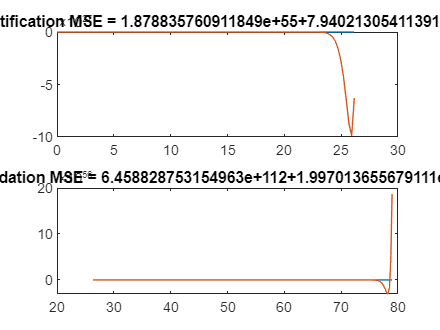

subplot(2,1,2);
plot(tval,yval,tval,y_val_cap); title("Validation MSE = " + string(mse_val))